% Author: Kenneth H.L. Ho
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

# Basic Image Processing 

## Download C.elegnas embryo (Kyoda et al., 2013), Image id=1, Z=30, t=0, from SSBD database

## Reading an image from file

url_image = "http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0"

url_image = "http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0"

k_img1 = imread(url_image)

k_img1 = 600×600×3 uint8 array
k_img1(:,:,1) =

    31    31    31    32    32    32    33    33    31    30    30    30    32    33    32    31    29    30    31    32    32    32    32    32    31    31    31    31    31    31    31    31    32    31    30    30    30    31    32    33    32    32    32    31    31    31    30    30    32    31    31    30    30    31    31    32    30    30    30    30    31    31    31    31    31    31    31    32    32    31    31    31    32    32    32    32    32    32    32    32    30    30    30    30    30    30    30    30    34    34    33    33    32    31    31    30    33    30    29    30    33    34    31    28    32    32    32    32    31    31    30    29    31    31    31    32    32    32    33    33    30    31    31    31    32    33    33    33    30    31    31    32    32    32    31    31    32    32    32    31    32    33    34    34    32    32    32    32    32    32    32    32    33    33    33    33    33    33    

imwrite(k_img1, 'k_image.tif', 'tif')

imfinfo('k_image.tif')

ans = struct with fields:
                     Filename: '/MATLAB Drive/k_image.tif'
                  FileModDate: '05-Aug-2019 10:50:14'
                     FileSize: 410726
                       Format: 'tif'
                FormatVersion: []
                        Width: 600
                       Height: 600
                     BitDepth: 24
                    ColorType: 'truecolor'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: [8 8 8]
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB'
                 StripOffsets: [1×67 double]
              SamplesPerPixel: 3
                 RowsPerStrip: 9
              StripByteCounts: [1×67 double]
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration: 'Chunky'
                    TileWid

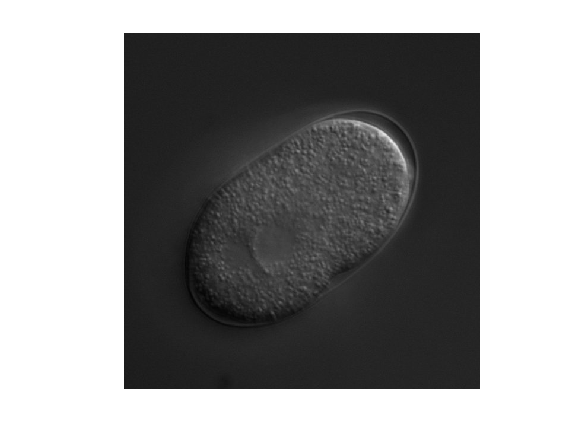

imshow('k_image.tif')

k_img1

k_img1 = 600×600×3 uint8 array
k_img1(:,:,1) =

    31    31    31    32    32    32    33    33    31    30    30    30    32    33    32    31    29    30    31    32    32    32    32    32    31    31    31    31    31    31    31    31    32    31    30    30    30    31    32    33    32    32    32    31    31    31    30    30    32    31    31    30    30    31    31    32    30    30    30    30    31    31    31    31    31    31    31    32    32    31    31    31    32    32    32    32    32    32    32    32    30    30    30    30    30    30    30    30    34    34    33    33    32    31    31    30    33    30    29    30    33    34    31    28    32    32    32    32    31    31    30    29    31    31    31    32    32    32    33    33    30    31    31    31    32    33    33    33    30    31    31    32    32    32    31    31    32    32    32    31    32    33    34    34    32    32    32    32    32    32    32    32    33    33    33    33    33    33    

size(k_img1)

ans =    600   600     3


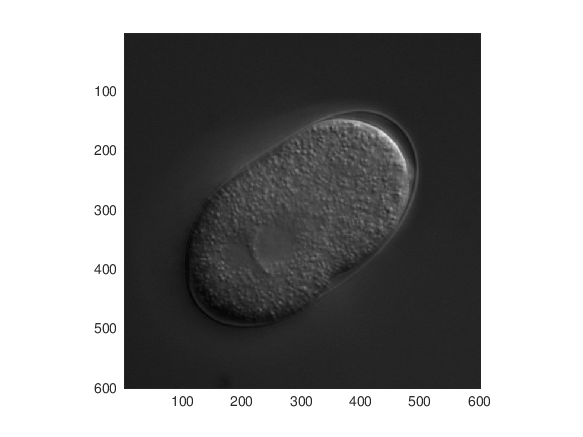

figure;
image(k_img1)
daspect([1,1,1])

whos k_img1

  Name          Size                 Bytes  Class    Attributes

  k_img1      600x600x3            1080000  uint8              



% Finding the minumum intensity on Red channel (or whichever as they are of
% the same value)
minvalue = min(min(k_img1(:,:,1)));
disp(minvalue)

   2



% Find the row and column of the image with the minimum intensity value.
[row, col] = find(k_img1(:,:,1)==minvalue);
disp([row, col])

   437   112
   464   158



k_img1(400:410,430:450,1)

ans = 11×21 uint8 matrix
   41   41   42   40   40   40   40   40   40   39   39   40   40   39   38   38   38   38   38   37   37
   40   40   40   40   39   38   38   40   41   40   38   41   41   40   40   39   39   40   40   39   39
   40   40   40   42   40   39   40   41   42   41   39   41   40   40   39   39   39   40   40   39   39
   40   40   39   41   40   40   40   41   41   41   40   41   40   40   39   39   39   39   40   39   39
   39   39   39   40   39   39   39   39   40   39   39   40   40   39   39   39   39   39   39   40   40
   40   41   41   39   39   40   39   39   39   39   40   40   40   39   39   39   39   39   39   40   40
   42   43   43   40   41   41   41   40   40   40   41   40   39   39   38   38   38   39   39   40   40
   42   42   42   39   41   42   41   40   39   40   42   40   39   39   38   38   38   38   39   41   40
   40   40   40   38   40   41   40   38   38   39   40   40   39   39   38   38   38   38   39   41   40
   41   42   42   41 

maxvalue = max(max(k_img1(:,:,1)))

maxvalue = uint8
238

disp(maxvalue)

   238



[row, col] = find(k_img1(:,:,1)==maxvalue);
disp([row, col])

   182   450
   182   451



k_img1(180:440,185:455,1)

ans = 261×271 uint8 matrix
   44   44   45   46   46   47   46   46   50   49   48   48   48   48   49   50   49   49   49   49   50   50   50   50   49   49   50   50   49   48   49   50   53   52   52   52   52   52   52   53   52   52   51   51   52   52   53   53   56   55
   45   46   46   46   46   45   45   45   45   46   47   47   47   47   46   45   50   50   50   50   50   50   51   51   47   49   50   49   49   49   50   51   53   53   52   52   52   52   53   53   52   52   52   52   52   53   54   54   56   56
   46   47   47   46   45   45   45   46   44   46   47   49   49   47   46   44   49   49   49   49   50   50   50   50   46   49   50   49   49   51   52   51   53   53   52   51   51   52   53   53   52   52   52   53   53   54   55   56   57   57
   45   46   47   46   45   45   46   48   47   48   49   49   49   49   48   47   49   49   50   50   50   50   50   50   48   52   53   50   50   52   53   52   53   53   52   51   51   52   53   53   53   53   53   54

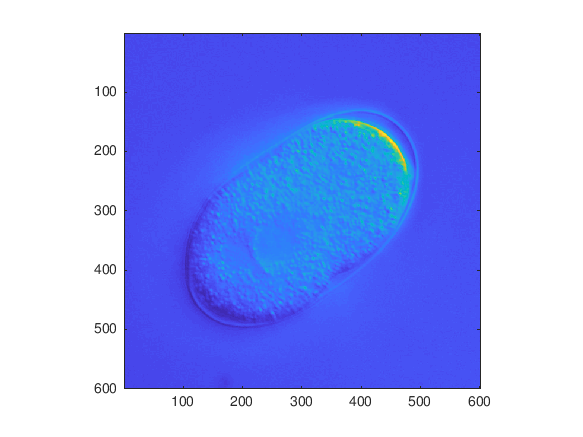

% converting rgb to indexed image
k_img2=rgb2gray(k_img1);

% image scaled colour function; using default colour map
imagesc(k_img2)
daspect([1,1,1])

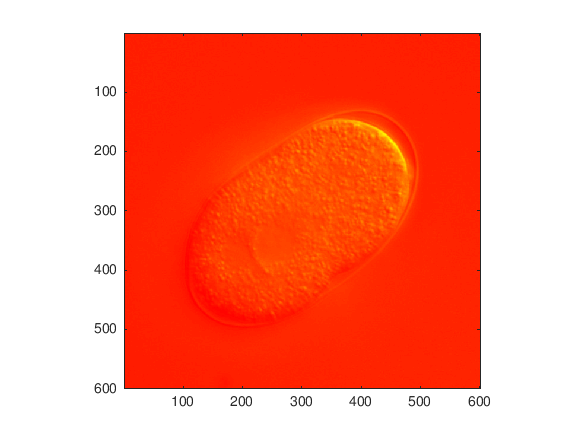

% using autumn colourmap
colormap("autumn");

imagesc(k_img2);
daspect([1,1,1])

% Thresholding
% display all the pixels that are larger than intensity 64
bw = k_img1 > 64;

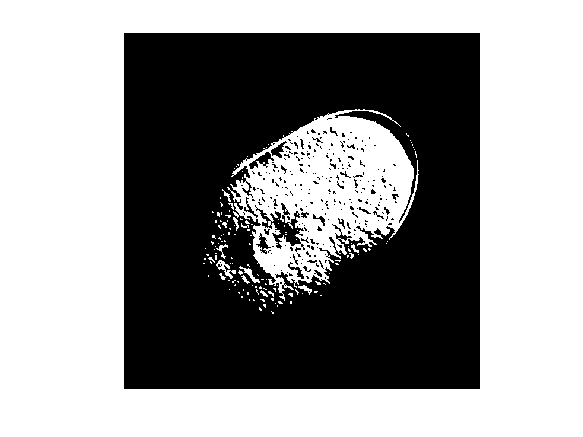

imshow(bw(:,:,1))

% thresholding at 128
bw = k_img1 > 128;

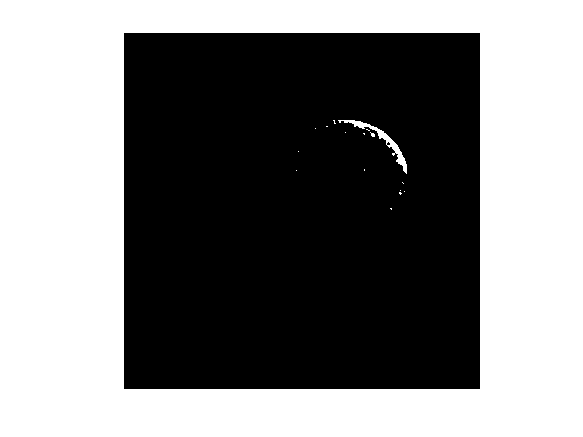

imshow(bw(:,:,1))

bw2 = k_img2 > 64

bw2 = 600×600 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

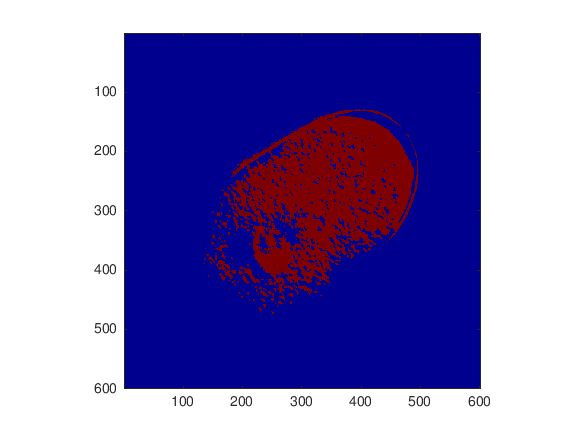

daspect([1,1,1])

imagesc(bw2)
daspect([1,1,1])

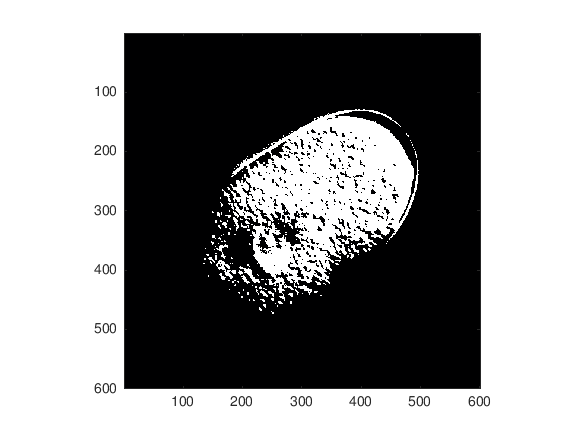

colormap(bone)
daspect([1,1,1])